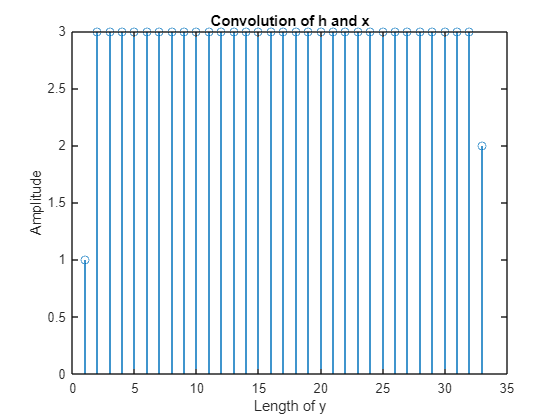

%EE451_Lab2
%Lisa Jacklin
%2023-09-08

h = [0.5 0.5];
x = [2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4 2 4];
y = conv(h, x);

figure; stem(y);
title("Convolution of h and x");
xlabel("Length of y"); ylabel("Amplitude");

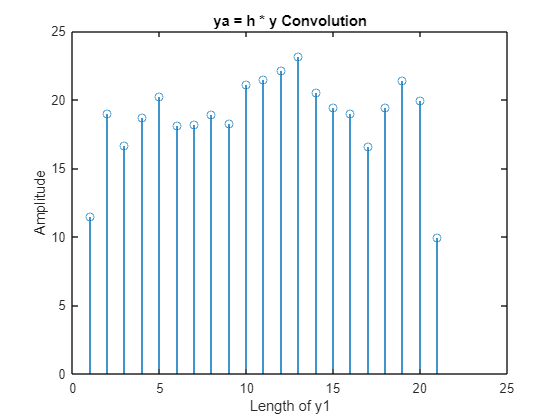

%now ya = h * (x+n)
na = randn(1, 20); %randn[array, length(t)] this gives a random gaussian
xa = 20+2*na;
x2 = na + xa;
%note that h for this one is the same as the example above
ts = 0.05;
t = 0:ts:4; %time ratio

%first plotting y1 = h*y
ya = conv(h, x2);

stem(ya);
title("ya = h * y Convolution");
xlabel("Length of y1"); ylabel("Amplitude")

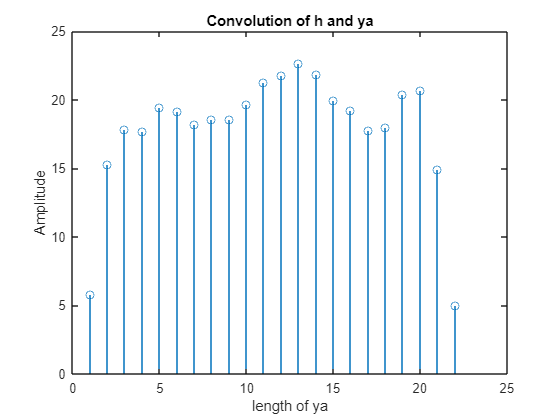

%Now, creating y1 = h* ya
y1 = conv(h, ya);

stem(y1);
title("Convolution of h and ya");
xlabel("length of ya"); ylabel("Amplitude");

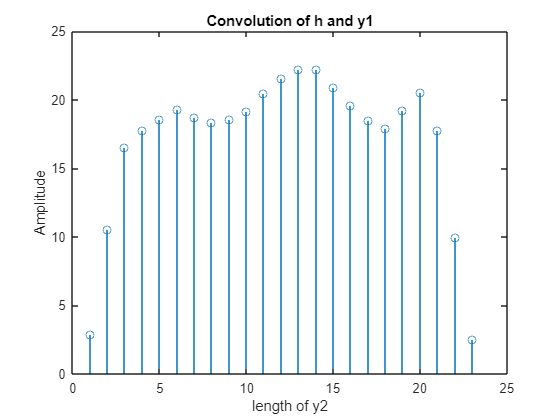

 %Now, creating y1 = h* y1
y2 = conv(h, y1);

stem(y2);
title("Convolution of h and y1");
xlabel("length of y2"); ylabel("Amplitude");

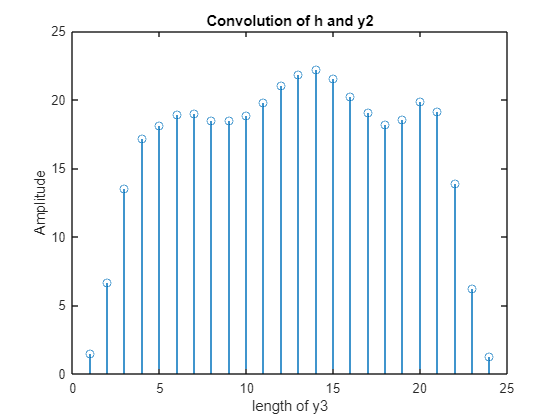

 %Now, creating y3 = h* y2
y3 = conv(h, y2);

stem(y3);
title("Convolution of h and y2");
xlabel("length of y3"); ylabel("Amplitude");

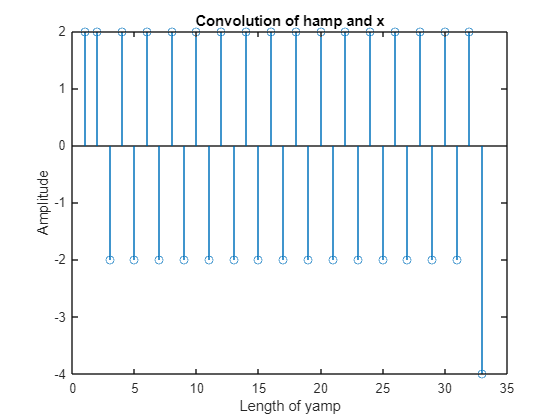

%note that this can be adjusted and changed to perform a multitude of time
%and it should become more evident over time that things are getting
%smoothed out using convolution.


%now to test with hamp = [1 -1]; this is suposed to amplify the signal
hamp = [1 -1];
yamp = conv(hamp, x);

stem(yamp);
title("Convolution of hamp and x");
xlabel("Length of yamp"); ylabel("Amplitude");

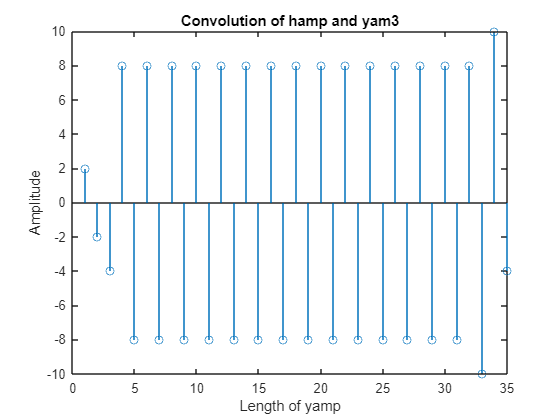

%now again to see what changes
yam2 = conv(hamp, yamp);
yam3 = conv(hamp, yam2);

stem(yam3);
title("Convolution of hamp and yam3");
xlabel("Length of yamp"); ylabel("Amplitude");

%trying the last problem on the slides
%h(n) = delta(n) + delta(n-1)
%x(n) = delta(n) + delta(n-1) + delta(n-2) + delta(n-3)

%find the output y(n) using 
%a. graphical methods of convolution
%b. convolution properties of delta(n)
